# Barnard CSC workshop: Experimenting with a computational model of a neuron

#### The Hodgkin-Huxley model

dt = 0.01;
tmax = 500; %ms
time = 0:dt:tmax;

The capacitance of the neuron is its membrane's capacity to store charge.

C_m = 100; %nF

The leak conductance is the amount of non-specific, passive ion channels in the membrane.

G_leak = 30; %nS

The sodium conductance represents the number of voltage-gated sodium channels in the membrane.

G_Na = 12000;

The potassium conductance represents the number of voltage-gated potassium channels in the membrane.

G_K = 360;

The equilibrium potentials for each conductance are the membrane voltages at which each particular ion type would find equilibrium and stop flowing.

E_leak = -70; %mV
E_Na = 50;
E_K = -80;

Try changing the parameters to find a regime where the neuron fires action potentials.

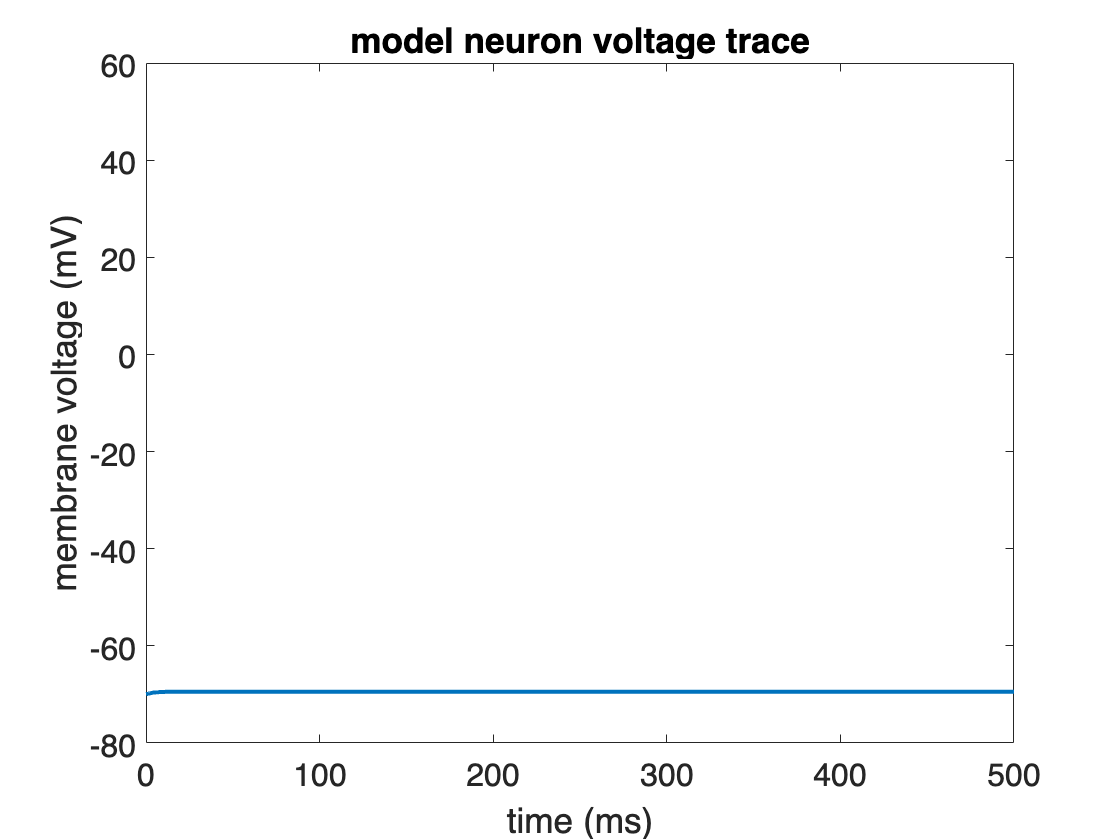

I_app = zeros(size(time)); %pA
I_app((time>50)&(time<450)) = 0; %0.05e3; %0.3e3;

V = zeros(size(time));
V(1) = E_leak;

m = zeros(size(time));
h = zeros(size(time));
n = zeros(size(time));

I_Na = zeros(size(time));
I_K = zeros(size(time));

for t = 2:length(time)
    Vm = V(t-1);

    % use Dayan and Abbott's rate constants
    alpha_m = (0.1.*(Vm+40.001))./(1-exp(-0.1.*(Vm+40.001)));
    beta_m = 4.*exp(-0.0556.*(Vm+65));

    alpha_h = 0.07.*exp(-0.05.*(Vm+65));
    beta_h = 1./(1+exp(-0.1.*(Vm+35)));

    alpha_n = (0.01.*(Vm+55.001))./(1-exp(-0.1.*(Vm+55.001)));
    beta_n = 0.125.*exp(-0.0125.*(Vm+65));

    % steady state gating variabls
    tau_m = 1./(alpha_m+beta_m);
    m_inf = alpha_m./(alpha_m+beta_m);

    tau_h = 1./(alpha_h+beta_h);
    h_inf = alpha_h./(alpha_h+beta_h);

    tau_n = 1./(alpha_n+beta_n);
    n_inf = alpha_n./(alpha_n+beta_n);

    if t<=2
        m(1) = m_inf(1);
        h(1) = h_inf(1);
        n(1) = n_inf(1);
    end

    m(t) = m(t-1) + (m_inf-m(t-1))*dt/tau_m;    % Update m

    h(t) = h(t-1) + (h_inf-h(t-1))*dt/tau_h;    % Update h

    n(t) = n(t-1) + (n_inf-n(t-1))*dt/tau_n;    % Update n

    I_Na(t) = G_Na*m(t)*m(t)*m(t)*h(t)*(E_Na-V(t-1)); % sodium current
    I_K(t) = G_K*n(t)*n(t)*n(t)*n(t)*(E_K-V(t-1));    % potassium current
    I_leak = G_leak*(E_leak - V(t-1));
    Itot = I_leak+I_Na(t)+I_K(t)+I_app(t);        % total current is sum of leak + active channels + applied current

    V(t) = V(t-1) + Itot*dt/C_m;                  % Update the membrane potential, V.

end

figure;
plot(time,V,'LineWidth',2)
xlabel('time (ms)')
ylabel('membrane voltage (mV)')
title('model neuron voltage trace')
set(gca,'FontSize',16)
ylim([-80 60])

% the experiment code block

I_step = 100; % picoAmps
V_experiment = HH_model(I_step); % milliVolts

% a plot of your results
% figure;
% plot(time,V_experiment,'LineWidth',2)
% xlabel('time (ms)')
% ylabel('membrane voltage (mV)')
% title('neuron with current injection')
% set(gca,'FontSize',16)

function V = HH_model(I_step)

% the time course of the simulation is specified here
% You might notice that this has also been created outside of this
% function. In general, this is a poor coding practice. But here it was
% done to make this function simpler to use for the purposes of this
% demonstration. Feel free to modify this function to make it more general
% purpose.
dt = 0.01;
tmax = 500; %ms
time = 0:dt:tmax;

% neuron parameters
C_m = 100; %nF
G_leak = 30; %nS
E_leak = -70; %mV

G_Na = 1.2e4;
E_Na = 50;

G_K = 0.036e4;
E_K = -80;

% here is where the applied current vector is created
I_app = zeros(size(time)); %pA
I_app((time>50)&(time<450)) = I_step; %0.3e3;

% initialization of variables
V = zeros(size(time));
V(1) = E_leak;

m = zeros(size(time));
h = zeros(size(time));
n = zeros(size(time));

% the for loop that solves the voltage eqn at each timestep
for t = 2:length(time)

    % use Dayan and Abbott's rate constants
    Vm = V(t-1);
    alpha_m = (0.1.*(Vm+40.001))./(1-exp(-0.1.*(Vm+40.001)));
    beta_m = 4.*exp(-0.0556.*(Vm+65));

    alpha_h = 0.07.*exp(-0.05.*(Vm+65));
    beta_h = 1./(1+exp(-0.1.*(Vm+35)));

    alpha_n = (0.01.*(Vm+55.001))./(1-exp(-0.1.*(Vm+55.001)));
    beta_n = 0.125.*exp(-0.0125.*(Vm+65));

    % steady state gating variabls
    tau_m = 1./(alpha_m+beta_m);
    m_inf = alpha_m./(alpha_m+beta_m);

    tau_h = 1./(alpha_h+beta_h);
    h_inf = alpha_h./(alpha_h+beta_h);

    tau_n = 1./(alpha_n+beta_n);
    n_inf = alpha_n./(alpha_n+beta_n);

    if t<=2
        m(1) = m_inf(1);
        h(1) = h_inf(1);
        n(1) = n_inf(1);
    end

    m(t) = m(t-1) + (m_inf-m(t-1))*dt/tau_m;    % Update m

    h(t) = h(t-1) + (h_inf-h(t-1))*dt/tau_h;    % Update h

    n(t) = n(t-1) + (n_inf-n(t-1))*dt/tau_n;    % Update n

    I_Na = G_Na*m(t)*m(t)*m(t)*h(t)*(E_Na-V(t-1)); % sodium current
    I_K = G_K*n(t)*n(t)*n(t)*n(t)*(E_K-V(t-1));    % potassium current
    I_leak = G_leak*(E_leak - V(t-1));
    I_total = I_leak + I_Na + I_K + I_app(t);        % total current is sum of leak + active channels + applied current

    V(t) = V(t-1) + I_total*dt/C_m;                  % Update the membrane potential, V.

end
end